Jesudara Omidokun

ECE 588 

Assignment #2:

-  Load the image "zoneplate.tif" and display the image and it's histogram 

- What is the range of values present in the image?

- Invert the image and print the inverted image and it's histrogram

Quesion 1 answer and result

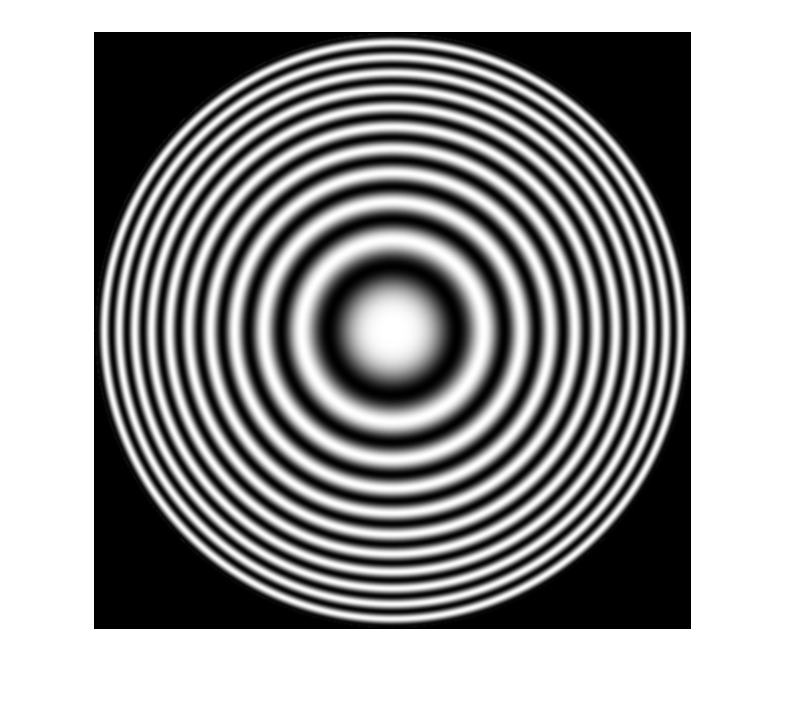

zplate=imread('zoneplate.tif');
imshow(zplate)

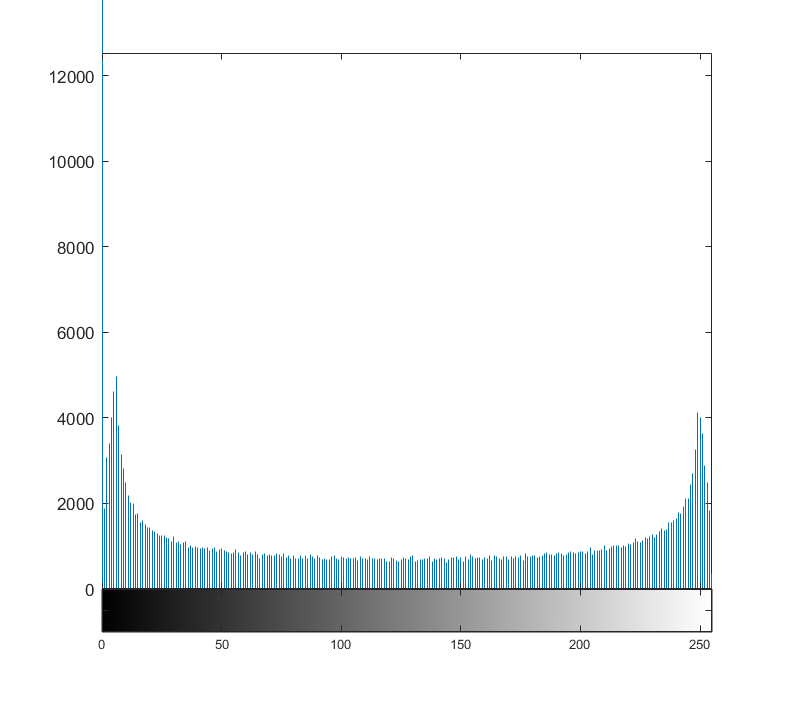

imhist(zplate)

Question 2 answer and result. 

Image pixel range

Max_zplate=max(max(zplate)) % maxmium of the rows and columns of the image.

Max_zplate = uint8
255

Min_zplate=min(min(zplate)) % minium of the rows and columns of the image

Min_zplate = uint8
0

range_zplate=Max_zplate - Min_zplate % range of value present in the image 

range_zplate = uint8
255

Question 3 answer and result.

Image Invert

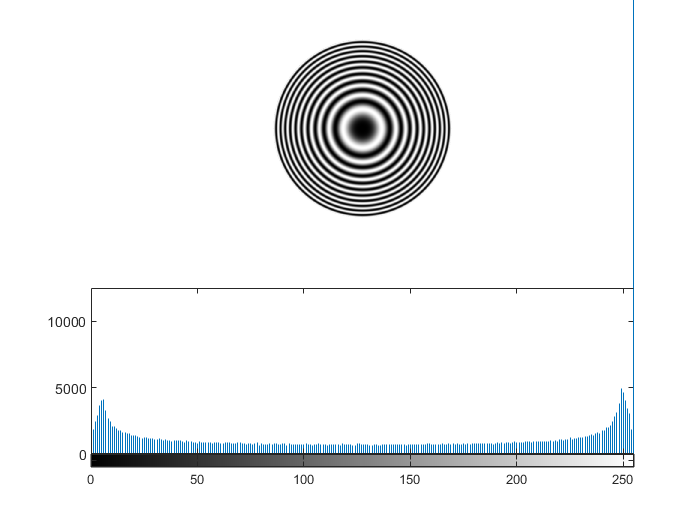

%% 3 Image invert 
% method 1 
zplate_inv=(Max_zplate-zplate);
figure
subplot(2,1,1)
imshow(zplate_inv)
subplot(2,1,2)
imhist(zplate_inv)

% method 2
X2 = imcomplement(zplate);
figure
subplot(2,1,1)
imshow(X2)
subplot(2,1,2)
imhist(X2)

This will read in the coefficients of digital filters.  These were designed using MATLAB's Signal Processing Toolbox and the fir1 function, so these are finite impulse response filters (and therefore stable).

lp1=dlmread('oneDlowpass1.txt');
lp2=dlmread('oneDlowpass2.txt');

4.  Plot both lp1 and lp2.

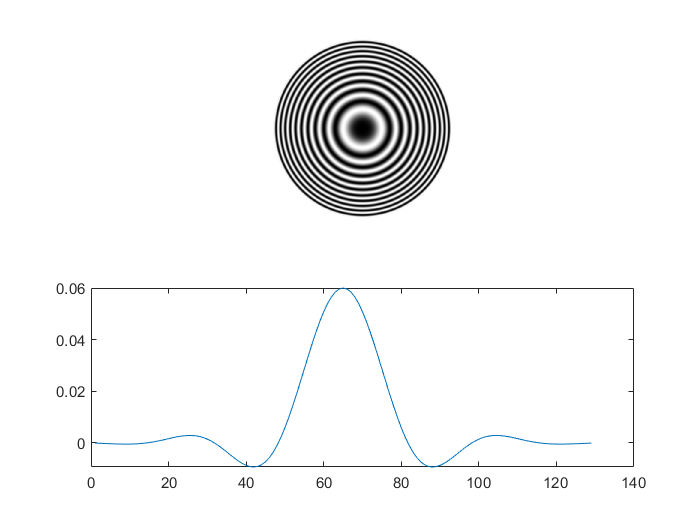

plot(lp1)

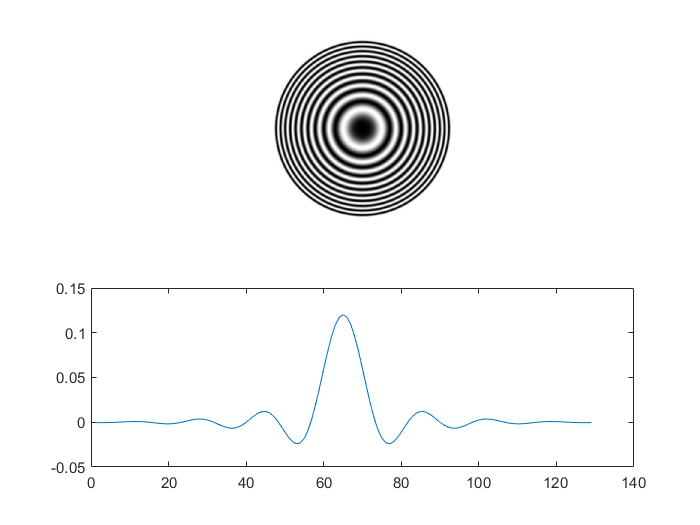

plot(lp2)

The following code will generate an impulse at the center of the length of the sequence.  Note that the Fourier Transform of a unit impulse is the constant 1.

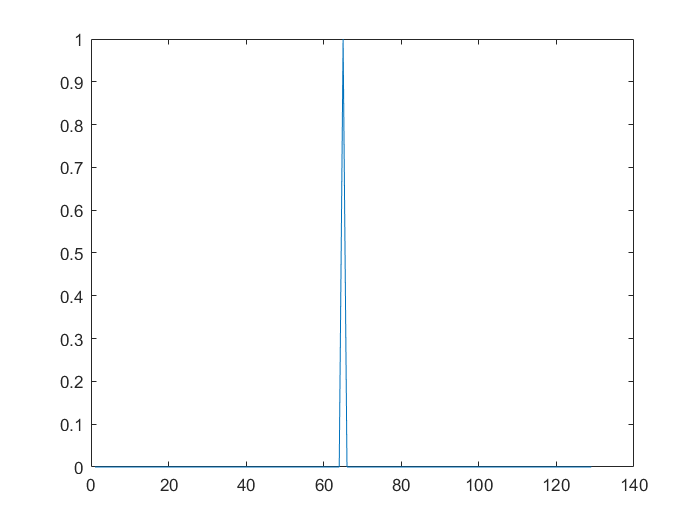

M_el=numel(lp1);
center=ceil(M_el/2);
oneDimpulse(1:M_el)=0;
oneDimpulse(center)=1;
figure, plot(oneDimpulse);

There are four main categories of filters:

- low pass

- high pass

- band reject ( notch )

- band pass

These can all be generated from a low pass filter and an impulse of the the correct size:

High Pass:  HP = Impulse - LP

HP1=oneDimpulse-lp1;
HP2=oneDimpulse-lp2;

Band Reject:  BR = LP + HP

BR1=lp1+HP1;
BR2=lp2+HP1;
BR3=lp1+HP2; 
BR4=lp2+HP2; %LP2+(impluse -LP2)

Since the LP will have a lower "cutoff frequency" than the high pass filter, this can be written as (HP2 just indicates the cutoff frequency used is different from LP1):

 Band Reject = LP1 + HP2

BR3;

Band Pass = Impulse - Band Reject

BP=oneDimpulse-BR3;

5.  Generate, using the given lp1 and lp2, the following filters:  the impulse used must be the same length as the low pass filter used, in this case the oneDimpulse has the correct length.

    a.  a high pass filter using lp2

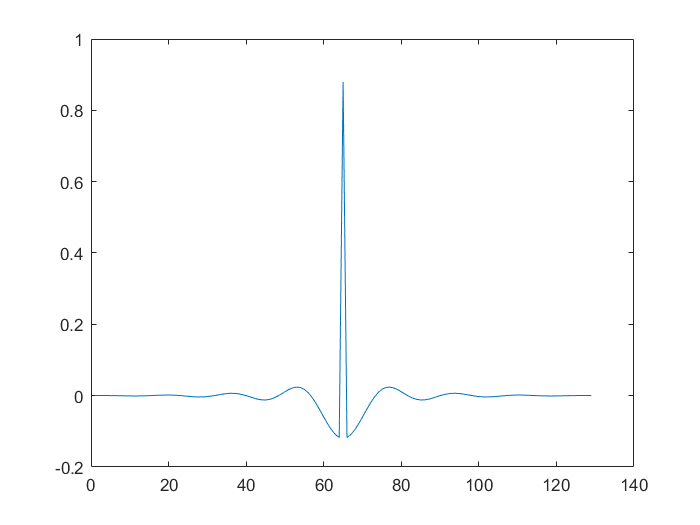

plot(HP2)

    b.  a band reject filter

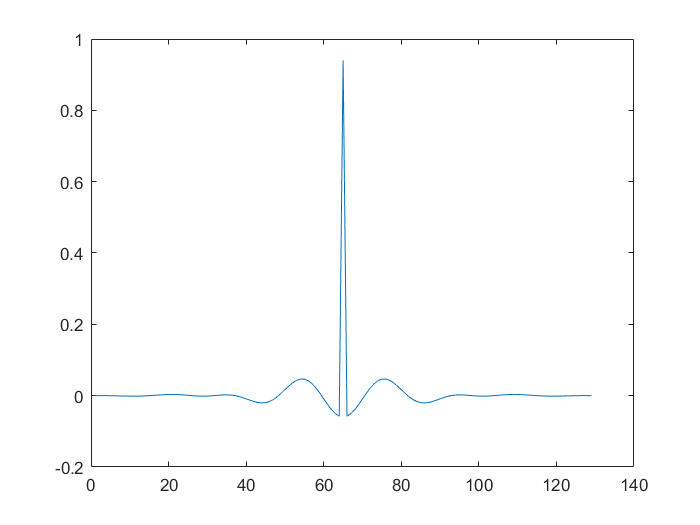

plot(BR3)

Based a on the looks of my first High pass and Band Reject filter, one can assume that they look similar but that i'll be a wrong asumption. it is much difficult to differential signals in time domain, that why we use frequency domain.  frequency domain helps tells more about the signal than the time domain.

Based on the look alike of High pass and Band Reject filter in the time domain, the following code line helps to differeniate the two signal plot. Assuming that if the signals are the same, the difference will be zero accross the time interval but if they are not the same, the difference will be shown in the plot immediately below. 

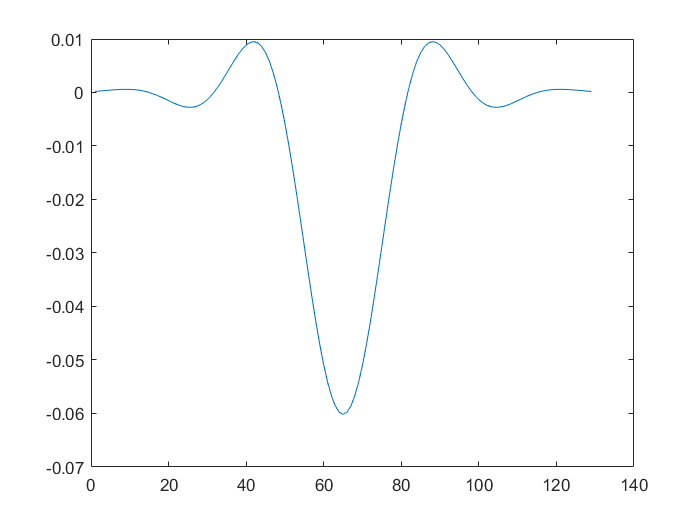


H222=HP2-BR3;
plot(H222)

 c.  a band pass filter

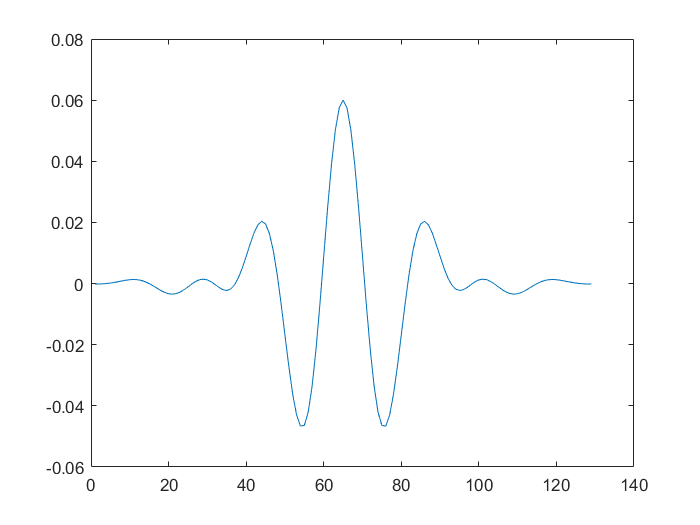

plot(BP)

6. There are several ways to generate a 2D filter from a given 1D filter.  It's possible to just generate a square matrix by multiplying the two 1D filters together.  This will work but will often generate ringing, so a windowing method is used to smooth the transition between edges of the image.  MATLAB has a built in function that makes this easy:  ftrans2

As an example:  to generate a 2D low pass filter using the coefficients of the filter given in lp1:

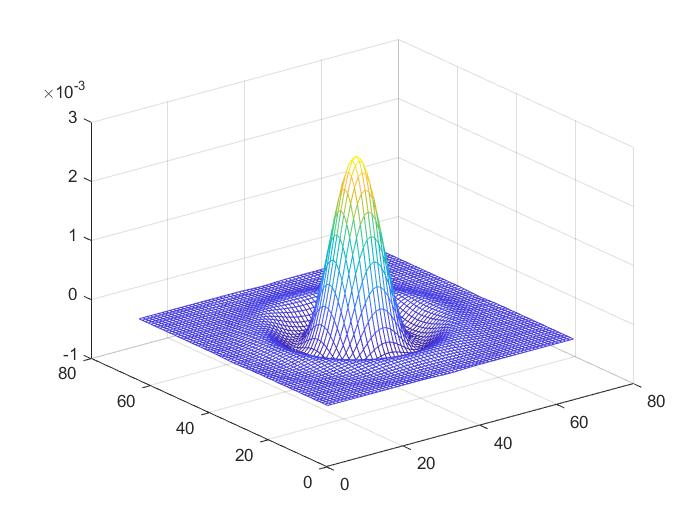

LP1_2D=ftrans2(lp1);
figure, mesh(LP1_2D(1:2:end,1:2:end))

High Pass

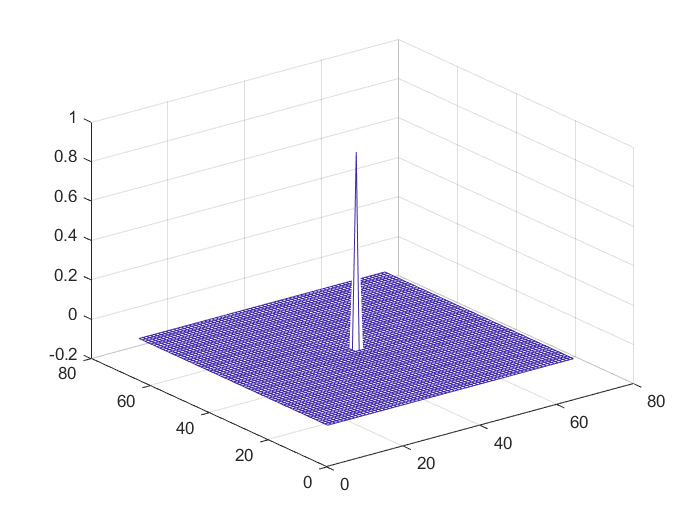

HP1_2D=ftrans2(HP1);
figure, mesh(HP1_2D(1:2:end,1:2:end))

HP2_2D=ftrans2(HP2);
figure, mesh(HP2_2D(1:2:end,1:2:end))

Band Reject 

BR1_2D=ftrans2(BR3);
figure, mesh(BR1_2D(1:2:end,1:2:end))

Band pass

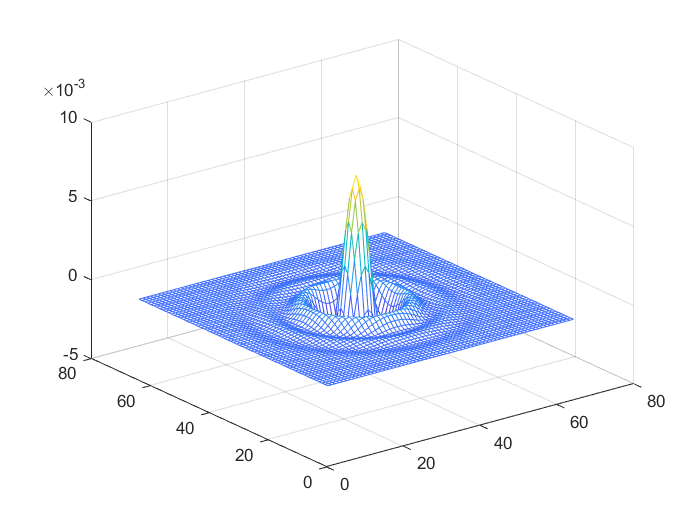

BP_2D=ftrans2(BP);
figure, mesh(BP_2D(1:2:end,1:2:end))

Now use this to lowpassfilter the image:  The plots above can be generated in similar fashion.

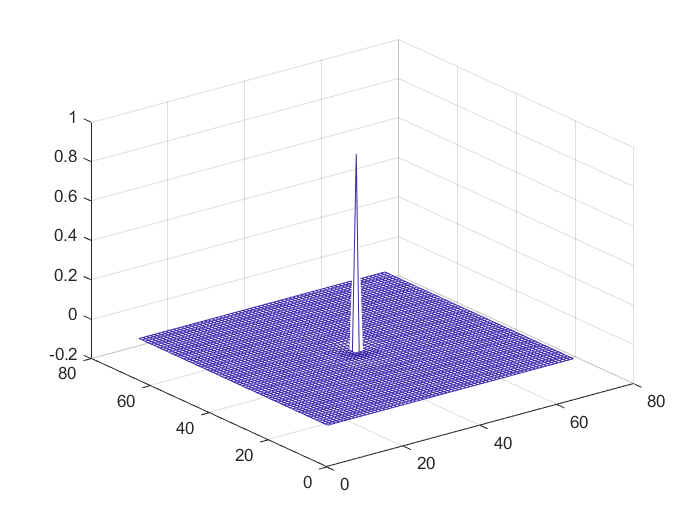

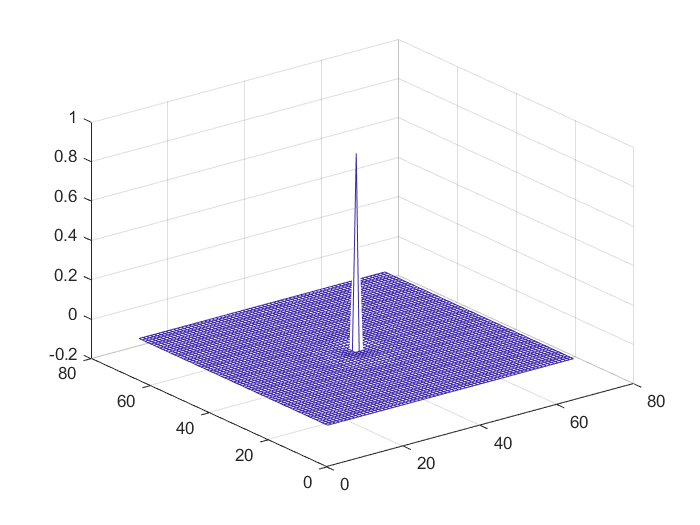

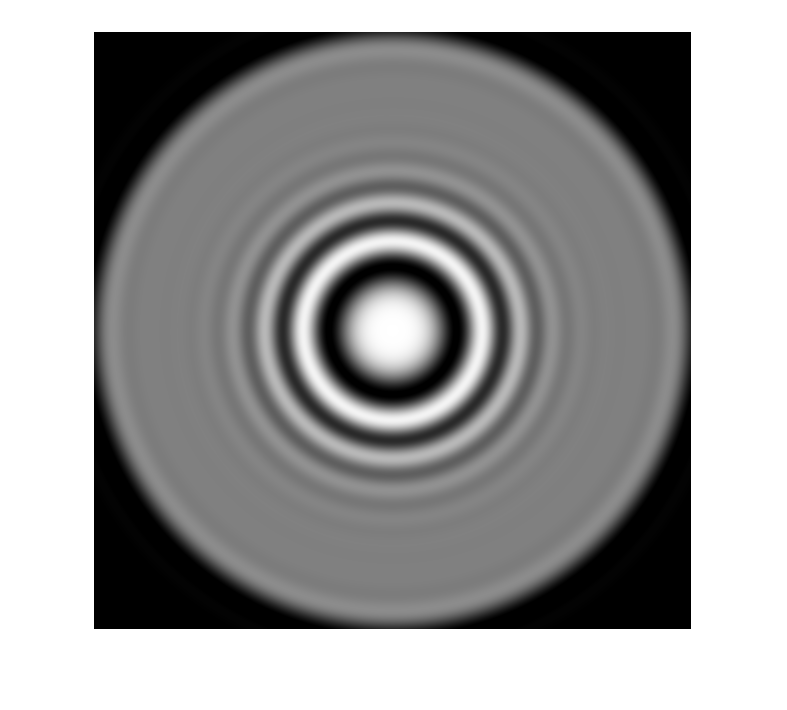

zplate_LP1 = imfilter(zplate, LP1_2D, 'replicate');
imshow(zplate_LP1,[])

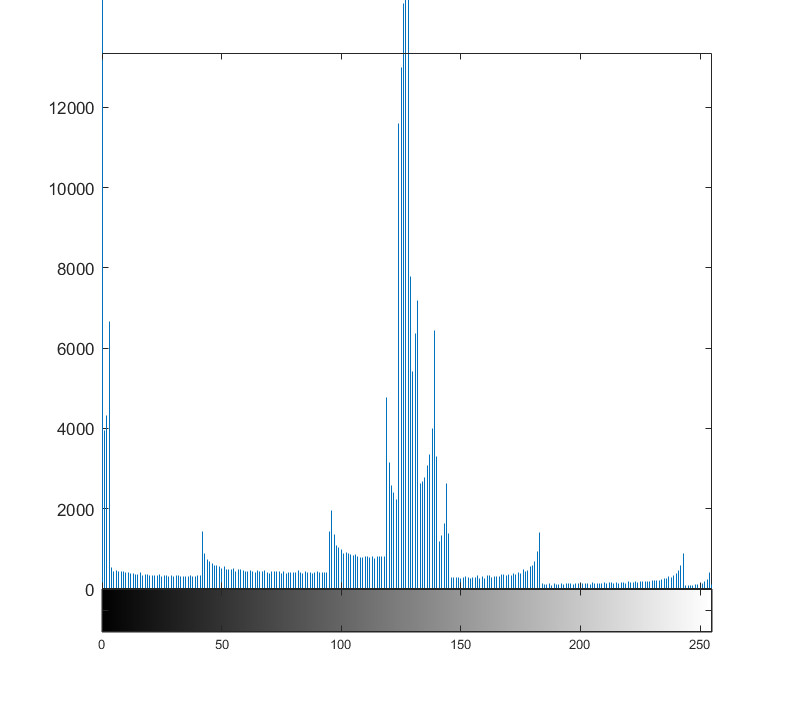

imhist(zplate_LP1)

High pass

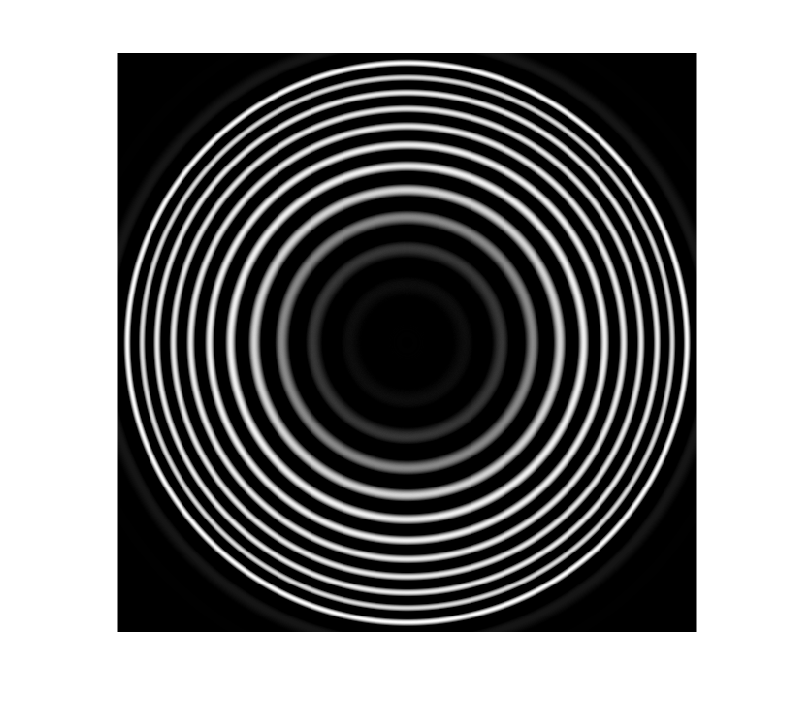

zplate_HP1 = imfilter(zplate, HP1_2D, 'replicate');
imshow(zplate_HP1,[])

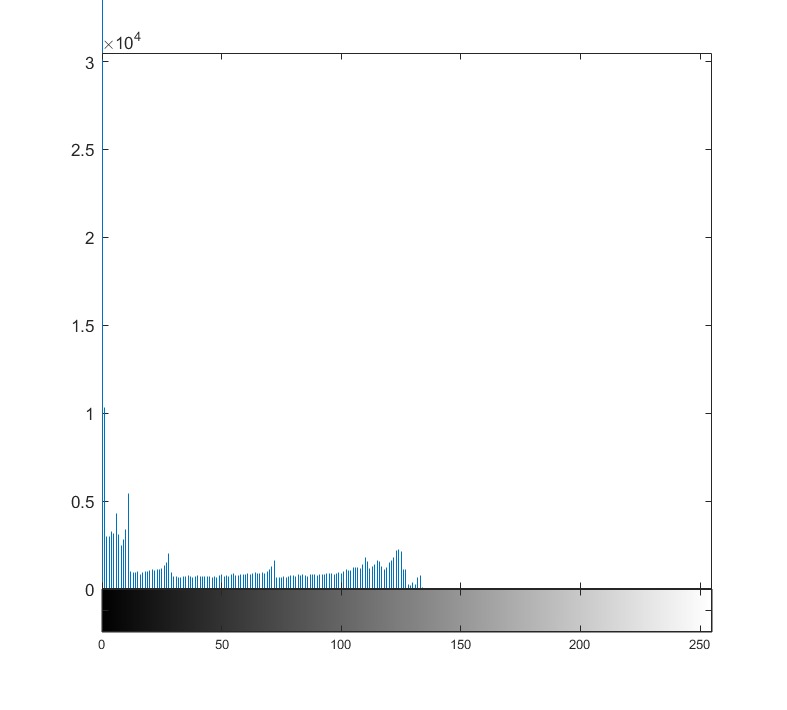

imhist(zplate_HP1)

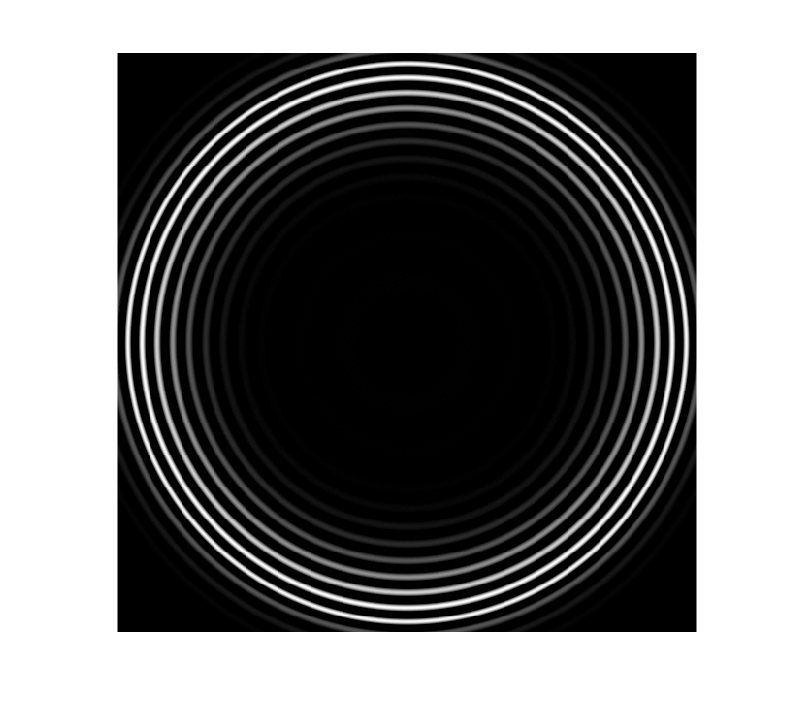

zplate_HP2 = imfilter(zplate, HP2_2D, 'replicate');
imshow(zplate_HP2,[])

Histrogram

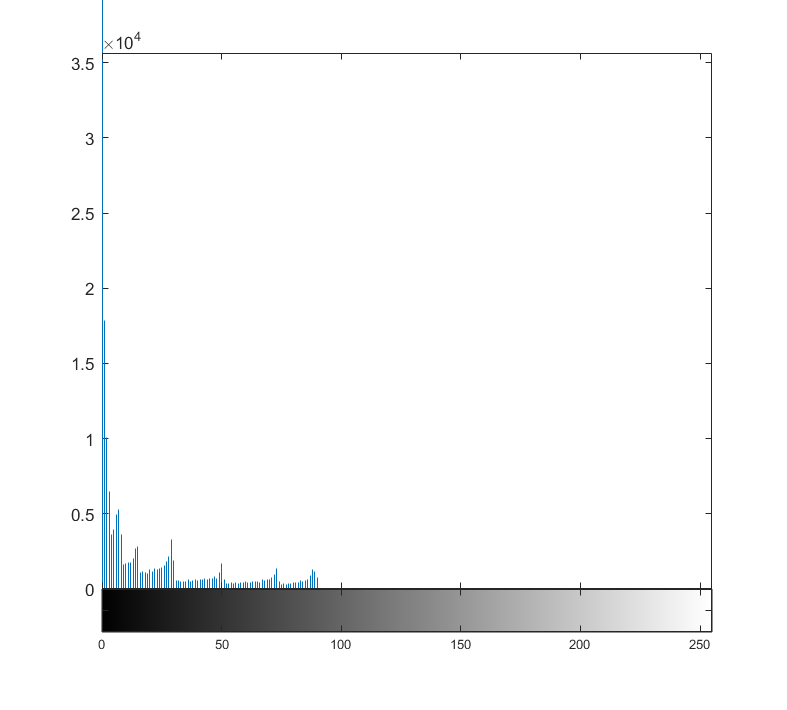

imhist(zplate_HP2)

Band-reject 

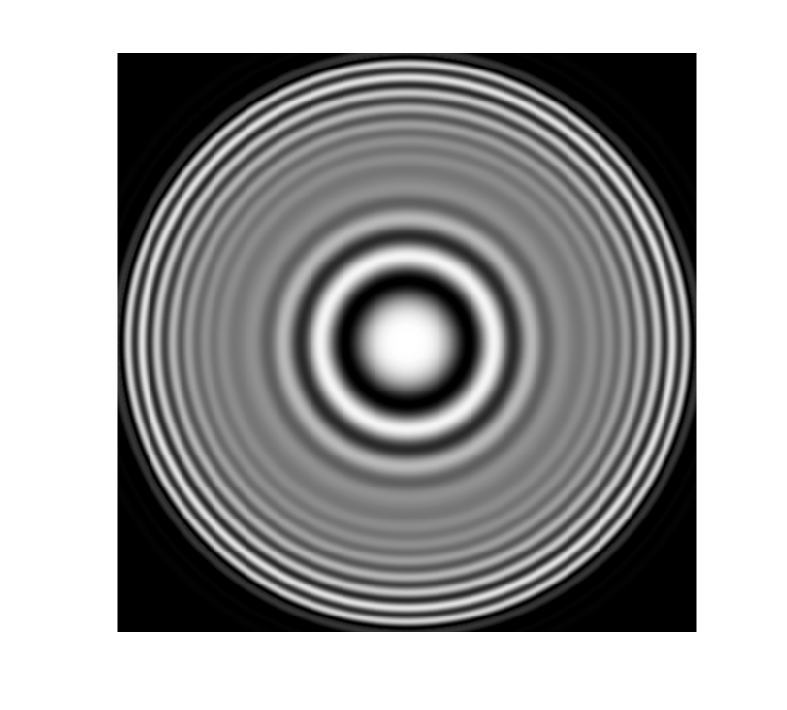

zplate_BR3 = imfilter(zplate, BR1_2D, 'replicate');
imshow(zplate_BR3,[])

Histrogram 

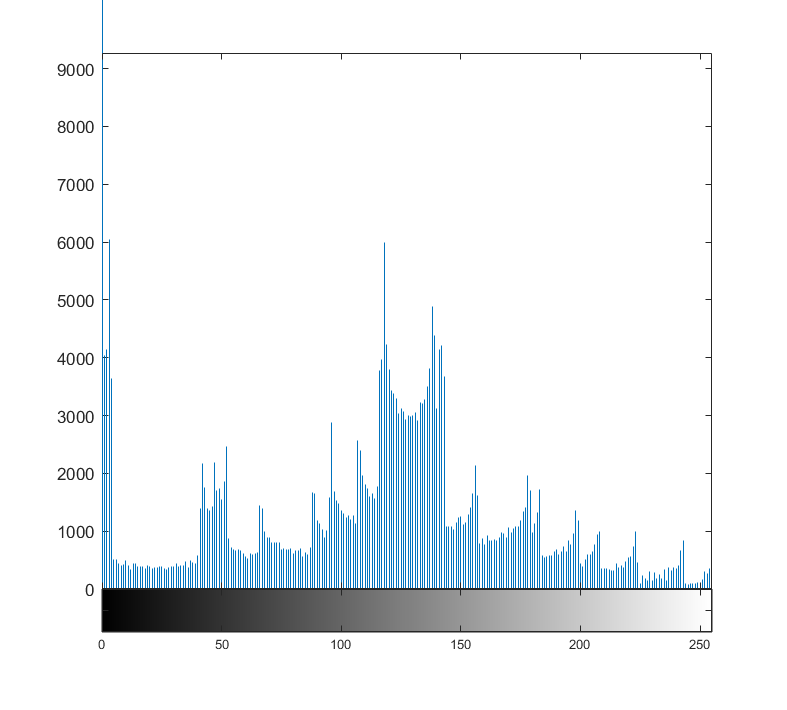

imhist(zplate_BR3)

Band Pass

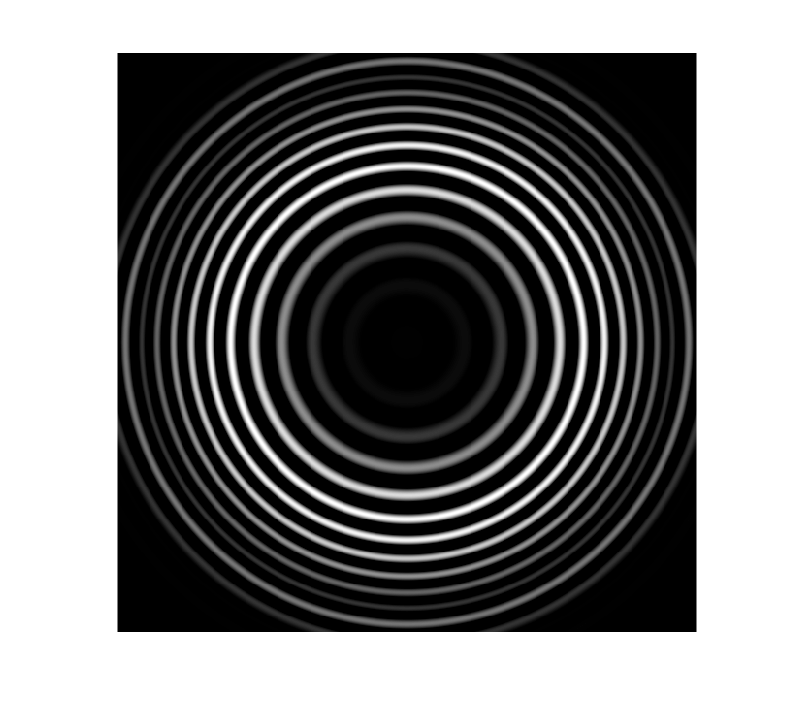

zplate_BP = imfilter(zplate, BP_2D, 'replicate');
imshow(zplate_BP,[])

Histrogram

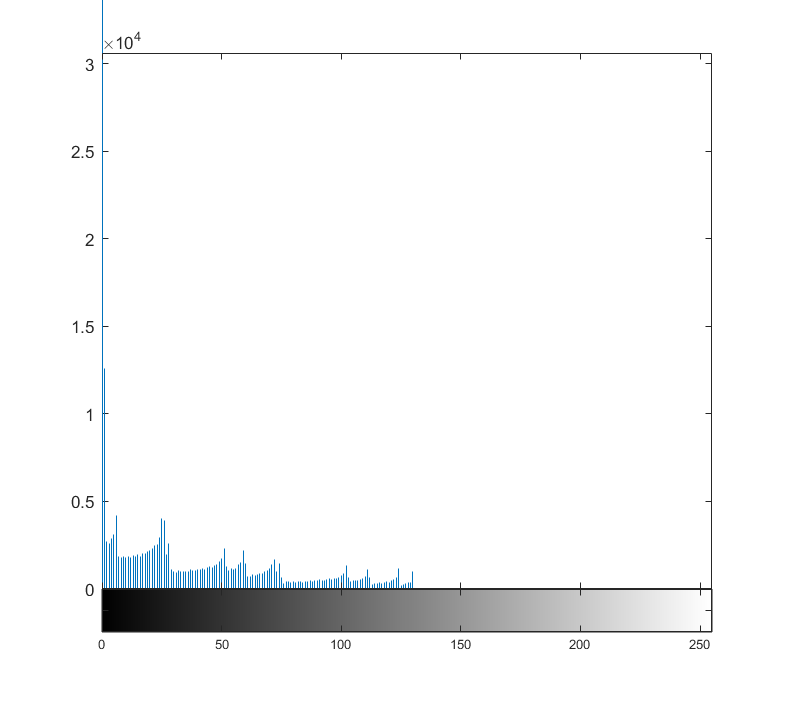

imhist(zplate_BP)

 Low pass filtering can be used to compensate for uneven illumation.  For example, the following checkerboard image has different shading, showing that the illumination is not consistent.  This code reads in the image, converts to double, then rescales the image to the range [0,1], to make computations take place in the same range.

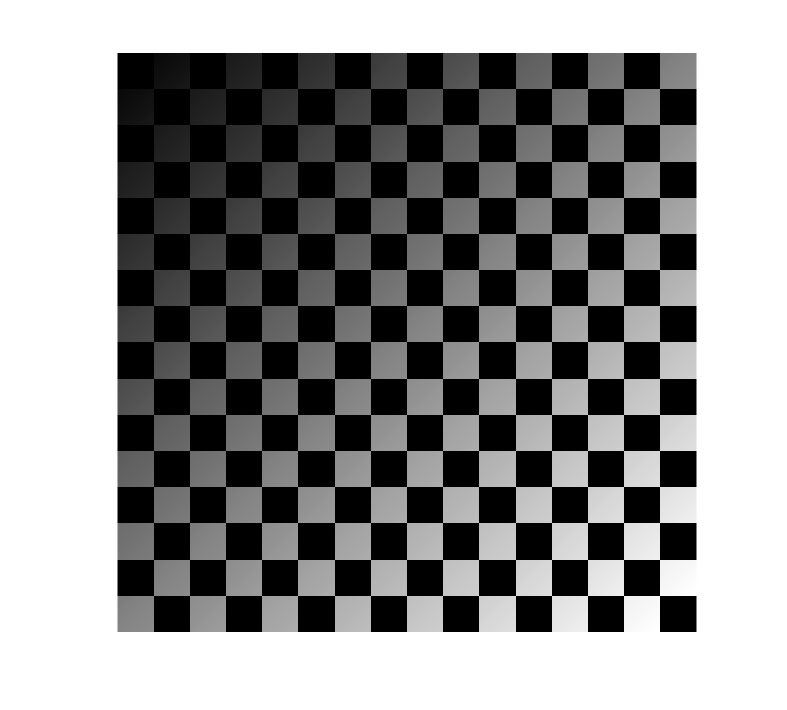

cb_shaded=im2double(imread("checkerboard1024-shaded.tif"));
cb_shaded=rescale(cb_shaded,0,1);
imshow(cb_shaded,[]);

7a.  Use a Gaussian filter to blur this image.  The result should be a consistent image that varies in instensity smoothly, with no evidence of the individual squares.  Use the imgaussfilt function to perform the blurring operationa and experiment with the value of sigma until the result is a smooth image.

Use the imshow command, with the [] option, to display your result and save the result in a variable.

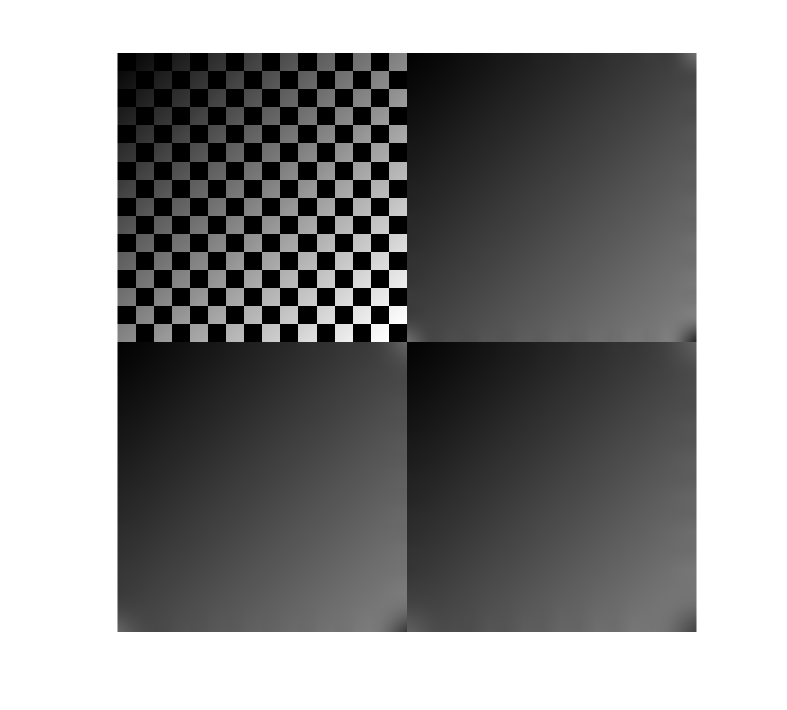


imblur=imgaussfilt(cb_shaded,50);
imblur1=imgaussfilt(cb_shaded,60);
imblur2=imgaussfilt(cb_shaded,80);
montage({cb_shaded,imblur,imblur1,imblur2})

7.b.  Now divide the original image by the the result in 7a.  Use the "elementwise" division, which in MATLAB is the ./ command

Plot the results with the imshow command.  It will be useful to use the [] option in imshow to scale the output.  

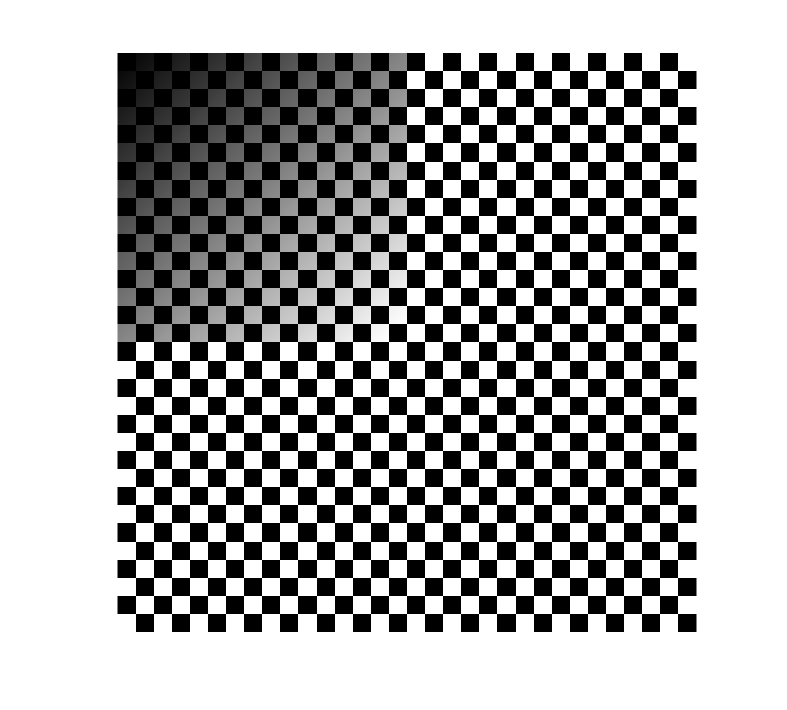

Outin=cb_shaded ./ imblur;
Outin1=cb_shaded ./ imblur1;
Outin2=cb_shaded ./ imblur2;

montage({cb_shaded, Outin, Outin1, Outin2},[])

Comment on the output.  With a correct amount of blur, the result should be a checkerboard pattern that does not have the shading strongly shown.  Does the result show a perfectly even checkerboard ?  Expalin using the intensity level from 7a, is that completely smoorth or does some variation exist?  Why ?

As shown above, I used various sigma value for the guassian filter. The observation is that the higher sigma value the more blur the image looks and clearer the final result of the checkerboard looks. The sigma values where the most significant result is shown are 60 and 80. The result shows close to prefect even checkerboard. The higher sigma value helps to lighten the shade in the checkboard, the high intensity level value increase the blurriness of the image.  The blurriness in the image helps to compensate for the variation in the pixel value. When a small pixel value is divided by a pixel value result is a increase in pixel value. This compensate for shade in the image.  